Задание 1) Проверьте свойства суммы векторов (источник [1], стр. 7),      используя векторы a=(2;3;4), b=(3;5;2), c=(1;1;1): сначала непосредственно (сумма 1 == сумма 2), затем используя функцию isequal( , ). Сделайте геометрическую интерпретацию.

a = [2, 3, 4];
b = [3, 5, 2];
c = [1, 1, 1];
figure;
if a + b + c == b + c + a
    disp("Yeah! it's equal");
end

Yeah! it's equal


if isequal(a + b + c, b + c + a)
    disp("Yeah! it's equal");
end

Yeah! it's equal


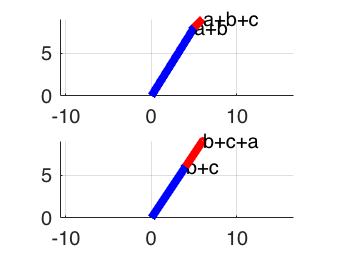

subplot(2, 1, 1);
hold on;
grid on;
axis equal;
quiver3(0, 0, 0, a(1) + b(1), a(2) + b(2), a(3) + b(3), "off", "filled", "LineWidth", 4, "Color", "blue");
text(a(1) + b(1), a(2) + b(2), a(3) + b(3), "a+b")
quiver3(a(1) + b(1), a(2) + b(2), a(3) + b(3), c(1), c(2), c(3), "off", "filled", "LineWidth", 4, "Color", "red");
text(a(1) + b(1) + c(1), a(2) + b(2) + c(2), a(3) + b(3) + c(3), "a+b+c")
hold off;
subplot(2, 1, 2);
hold on;
grid on;
axis equal;
quiver3(0, 0, 0, b(1) + c(1), b(2) + c(2), b(3) + c(3), "off", "filled", "LineWidth", 4, "Color", "blue");
text(b(1) + c(1), b(2) + c(2), b(3) + c(3), "b+c");
quiver3(b(1) + c(1), b(2) + c(2), b(3) + c(3), a(1), a(2), a(3), "off", "LineWidth", 4, "Color", "red");
text(b(1) + c(1) + a(1), b(2) + c(2) + a(2), b(3) + c(3) + a(3), "b+c+a");
hold off;

Задание 2) Проверьте свойства умножения вектора на число (1,2,3 согласно источнику [1], стр. 29) на следующих векторах: a=(4,2,3), b=(1,5,2) и числах: α=4, β=3. Используйте isequal.

a = [4, 2, 3];
b = [1, 5, 2];
if isequal(4 * a + 4 * b, 4 * (a + b))
    disp("Yeah! It's equal");
end

Yeah! It's equal


if (isequal(3 * a + 3 * b, 3 * (a + b)))
    disp("Yeah! It's equal");
end

Yeah! It's equal


Задание 3) Длину вектора  a = {3, 4, 5} вычислите по определению ([1], стр. 30) и с помощью встроенной функции norm(). Вычислите орт а0 (найдите его координаты). Проверьте, является ли вычисленный вектор единичным (isequal). Изобразите оба вектора. Сделайте то же самое для вектора b = {4, 2}.

figure;
a = [3, 4, 5];
l_opr = sqrt(a(1) * a(1) + a(2) * a(2) + a(3) * a(3));
l_nor = norm(a);
if isequal(l_nor, l_opr)
    disp("Yeah! Function works correctly.");
end

Yeah! Function works correctly.


ort_a = a / l_nor;
if isequal(norm(ort_a), 1)
    disp("Ort A is vector:");
    disp(ort_a);
end

Ort A is vector:


    0.4243    0.5657    0.7071



subplot(2, 1, 1);
hold on;
quiver3(0, 0, 0, a(1), a(2), a(3), "off", "filled", "LineWidth", 4, "Color", "red");
quiver3(0, 0, 0, ort_a(1), ort_a(2), ort_a(3), "off", "filled", "LineWidth", 3, "Color", "blue");
hold off;

b = [4, 2];
ort_b = b / norm(b);

if isequal(norm(ort_b), 1)
    disp("Ort B is vector:");
    disp(ort_b);
end

Ort B is vector:


    0.8944    0.4472



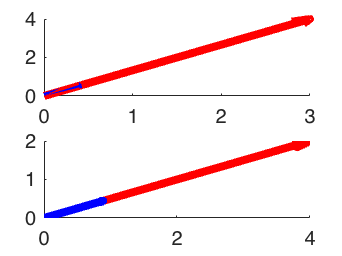

subplot(2, 1, 2);
hold on;
quiver(0, 0, b(1), b(2), "off", "filled", "LineWidth", 4, "Color", "red");
quiver(0, 0, ort_b(1), ort_b(2), "off", "filled", "LineWidth", 4, "Color", "blue");
hold off;

Задание 4) Вычислите в градусах углы наклона вектора a = {3, 4, 5} к осям координат. Проверьте, что сумма квадратов направляющих косинусов вектора будет равна единице. Сделайте то же самое для вектора b = {4, 2}.

a = [3, 4, 5];
cos_ax = a(1) / norm(a);
cos_ay = a(2) / norm(a);
cos_az = a(3) / norm(a);
disp("Angle of vector a with Ox:");

Angle of vector a with Ox:


disp(acosd(cos_ax));

   64.8959



disp("Angle of vector a with Oy:");

Angle of vector a with Oy:


disp(acosd(cos_ay));

   55.5501



disp("Angle of vector a with Oz:");

Angle of vector a with Oz:


disp(acosd(cos_az));

   45.0000



if isequal(round(cos_ax^2  + cos_ay^2 + cos_az^2), 1)
    disp("Sum of cosines is equal to 1");
end

Sum of cosines is equal to 1



b = [4, 2];
cos_bx = b(1) / norm(b);
cos_by = b(2) / norm(b);
disp("Angle of vector b with Ox:");

Angle of vector b with Ox:


disp(acosd(cos_bx));

   26.5651



disp("Angle of vector b with Oy:");

Angle of vector b with Oy:


disp(acosd(cos_by));

   63.4349



if isequal(round(cos_bx^2 + cos_by^2), 1)
    disp("Sum of cosines is equal to 1");
end

Sum of cosines is equal to 1


Задание 5) Векторы a = {1, -2, 0}, b = {0, 1, 1} и c = {1, 2, 2} образуют базис (покажите, что векторы некомпланарны). Изобразите эти векторы с помощью функций line и plot3. Изобразите координатные орты  черным цветом, толщиной ‘LineWidth’, 4.Вычислите и изобразите орты векторов  толщиной ‘LineWidth’, 4.

figure;
a = [1, -2, 0];
b = [0, 1, 1];
c = [1, 2, 2];
ort_a = a / norm(a);
ort_b = b / norm(b);
ort_c = c / norm(c);
if dot(cross(a, b), c) ~= 0
    disp("Vectors are not coplanar");
end

Vectors are not coplanar


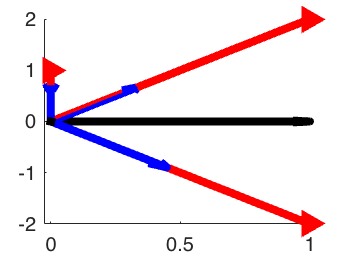

hold on;
line([0 0 0; 1 0 1], [0 0 0; -2 1 2], [0 0 0; 0 1 2], "LineWidth", 4, "Color", "red");
plot3([1 0], [-2 1], [0 1], ">","LineWidth", 4, "Color", "red");
plot3(1, 2, 2, ">", "LineWidth", 4, "Color", "red");
quiver3([0 0 0], [0 0 0], [0 0 0], [1 0 0], [0 1 0], [0 0 1], "off", "filled", 'LineWidth', 4, "Color", "black");
quiver3([0 0 0], [0 0 0], [0 0 0], [ort_a(1) ort_b(1) ort_c(1)], [ort_a(2) ort_b(2) ort_c(2)], [ort_a(3) ort_b(3) ort_c(3)], "off", "filled", "LineWidth", 4, "Color", "blue");
hold off;

Задание 6) Векторы  **p** = {2,-3}  и  **q** = {1,2} образуют базис (покажите, что векторы неколлинеарны).  Найдите разложение вектора **s** = {9,4}  по базису **p** и **q**: **s** =m**p** + n**q**. Изобразите  векторы **p**, **q** , m**p**, n**q**, **s**,  а также координатные оси Ox и Oy и  координатные орты **i**, **j**.

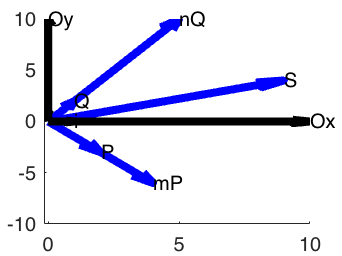

figure;
p = [2, -3];
q = [1, 2];
s = [9, 4];
A = [2, 1; -3, 2];
b = [9; 4];
m = A \ b;
hold on;
quiver([0, 0, 0, 0, 0], [0, 0, 0, 0, 0], [2, 1, 9, m(1) * p(1), m(2) * q(1)], [-3, 2, 4, m(1) * p(2), m(2) * q(2)], "off", "filled", "LineWidth", 4, "Color", "blue");
text(9, 4, "S");
text(2, -3, "P");
text(1, 2, "Q");
text(m(1) * p(1), m(1) * p(2), "mP");
text(m(2) * q(1), m(2) * q(2), "nQ");
quiver([0, 0, 0, 0], [0, 0, 0, 0], [10, 0, 1, 0], [0, 10, 0, 1], "off", "filled", "LineWidth", 4, "Color", "black");
text(10, 0, "Ox");
text(1, 0, "i");
text(0, 1, "j");
text(0, 10, "Oy");
hold off;

Задание 7) На плоскости даны три вектора **a** = {3,2}, **b** = {-2,1}, **c** = {4,-4}. Определите разложение каждого из этих трёх векторов, принимая в качестве базиса  два других. Графическое окно разбейте на четыре области.  Во всех окнах изобразите координатные оси Ox и Oy,  орты **i**, **j**. В первом изобразите три вектора. В оставшихся трёх – геометрическую интерпретацию разложения каждого из этих трёх векторов по двум остальным. Векторы базиса представьте синим цветом, разлагаемый вектор – красным. 

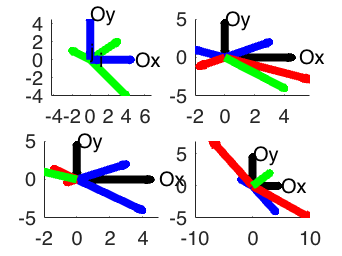

a = [3, 2];
b = [-2, 1];
c = [4, -4];
subplot(2, 2, 1);
hold on;
axis equal;
quiver([0 0 0], [0 0 0], [3 -2 4], [2 1 -4], "off", "filled", "LineWidth", 4, "Color", "green");
quiver([0 0 0 0], [0 0 0 0], [5 0 1 0], [0 5 0 1], "LineWidth", 4, "Color", "blue");
text(5, 0, "Ox");
text(1, 0, "i");
text(0, 1, "j");
text(0, 5, "Oy");
hold off;
subplot(2, 2, 2);
hold on;
quiver([0 0 0 0], [0 0 0 0], [5 0 1 0], [0 5 0 1], "LineWidth", 4, "Color", "black");
text(5, 0, "Ox");
text(1, 0, "i");
text(0, 1, "j");
text(0, 5, "Oy");
A = [3, -2; 2, 1];
B = [4; -4];
m = A \ B;
quiver([0 0], [0 0], [3, -2], [2, 1], "off", "filled", "LineWidth", 4, "Color", "blue");
quiver([0 0], [0 0], [m(1) * a(1), m(2) * b(1)], [m(1) * a(2), m(2) * b(2)], "off", "filled", "LineWidth", 4, "Color", "red");
quiver(0, 0, 4, -4, "off", "filled", "LineWidth", 4, "Color", "green");
hold off;
subplot(2, 2, 3);
hold on;
quiver([0 0 0 0], [0 0 0 0], [5 0 1 0], [0 5 0 1], "LineWidth", 4, "Color", "black");
text(5, 0, "Ox");
text(1, 0, "i");
text(0, 1, "j");
text(0, 5, "Oy");
A = [3, 4; 2, -4];
B = [-2; 1];
m = A \ B;
quiver([0 0], [0 0], [3, 4], [2, -4], "off", "filled", "LineWidth", 4, "Color", "blue");
quiver([0 0], [0 0], [m(1) * a(1), m(2) * c(1)], [m(1) * a(2), m(2) * c(2)], "off", "filled", "LineWidth", 4, "Color", "red");
quiver(0, 0, -2, 1, "off", "filled", "LineWidth", 4, "Color", "green");
hold off;
subplot(2, 2, 4);
hold on;
quiver([0 0 0 0], [0 0 0 0], [5 0 1 0], [0 5 0 1], "LineWidth", 4, "Color", "black");
text(5, 0, "Ox");
text(1, 0, "i");
text(0, 1, "j");
text(0, 5, "Oy");
A = [-2, 4; 1, -4];
B = [3; 2];
m = A \ B;
quiver([0 0], [0 0], [-2, 4], [1, -4], "off", "filled", "LineWidth", 4, "Color", "blue");
quiver([0 0], [0 0], [m(1) * b(1), m(2) * c(1)], [m(1) * b(2), m(2) * c(2)], "off", "filled", "LineWidth", 4, "Color", "red")
quiver(0, 0, 3, 2, "off", "filled", "LineWidth", 4, "Color", "green");
hold off;

Задание 8) Даны четыре вектора **a** = {2,1,0}, **b** = {1,-1,2},  **c** = {2,2,-1} и **d** = {3,7,-7}. Определите разложение вектора **а**, принимая в качестве базиса три остальных вектора. Сделайте геометрическую интерпретацию задачи на 2 рисунках. На первом рисунке изобразите координатные оси, орты осей и четыре вектора. На втором – геометрическую интерпретацию разложения вектора **а**. Векторы базиса представьте синим цветом, разлагаемый вектор – красным.

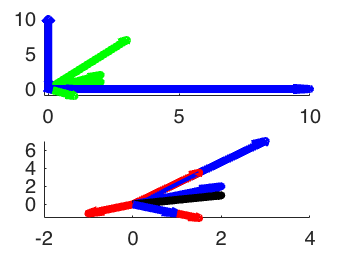

figure;
a = [2 1 0];
b = [1 -1 2];
c = [2 2 -1];
d = [3 7 -7];
subplot(2,1,1);
hold on;
quiver3([0 0 0 0], [0 0 0 0], [0 0 0 0], [2 1 2 3], [1 -1 2 7], [0 2 -1 -7], "off", "filled", "LineWidth", 4, "Color", "green");
quiver3([0 0 0 0 0 0], [0 0 0 0 0 0], [0 0 0 0 0 0], [10 0 0 1 0 0], [0 10 0 0 1 0], [0 0 10 0 0 1], "off", "filled", "LineWidth", 4, "Color", "blue");
hold off;
subplot(2, 1, 2);
hold on;
A = [1 2 3; -1 2 7; 2 -1 -7];
B = [2; 1; 0];
m = A \ B;
quiver3([0 0 0], [0 0 0], [0 0 0], [1 2 3], [-1 2 7], [2 -1 -7], "off", "filled", "LineWidth", 4, "Color", "blue");
quiver3([0 0 0], [0 0 0], [0 0 0], [m(1) * b(1), m(2) * c(1), m(3) * d(1)], [m(1) * b(2), m(2) * c(2), m(3) * d(2)], [m(1) * b(3), m(2) * c(3), m(3) * d(3)], "off", "filled", "LineWidth", 4, "Color", "red");
quiver3(0, 0, 0, 2, 1, 0, "off", "filled", "LineWidth", 4, "Color", "black");
hold off;

Задание 9) Даны векторы **a** = {-1,2,0}, **b** = {0,1,2} и  **c** = {1,2,2}. Используя функцию isequal, проверьте свойства 1, 2, 2’, 3, 3’, 4 скалярного произведения векторов ([1], стр. 40).

a = [-1 2 0];
b = [0 1 2];
c = [1 2 2];
isequal(dot(a, b), dot(b, a))

ans = logical
   1


isequal(dot(a + b, c), dot(a, c) + dot(b, c))

ans = logical
   1


isequal(dot(a, b + c), dot(a, c) + dot(a, c))

ans = logical
   0


isequal(dot(2 * a, b), 2 * dot(a, b))

ans = logical
   1


isequal(dot(a, b * 2), 2 * dot(a, b))

ans = logical
   1


if ~isequal(a, [0 0 0])
    disp("a is not 0");
    disp(dot(a, a) > 0);
end

a is not 0


   1




if isequal(a, [0 0 0])
    disp("a is 0");
    disp(isequal(dot(a, a), 0));
end

Задение 10)Даны векторы **a** = {-1,2,0}, **b** = {0,1,2} и  **c** = {1,2,2}. Используя функцию isequal, убедитесь в невыполнении равенств (2), (3), (4) ([1], стр. 40).

a = [-1 2 0];
b = [0 1 2];
c = [1 2 2];

disp(isequal(a * dot(b, c), dot(a, b) * c));

   0



disp(isequal(dot(a, b), dot(a, c)));

   0



disp(isequal(dot(a, b) * b, a * dot(b, b)));

   0

